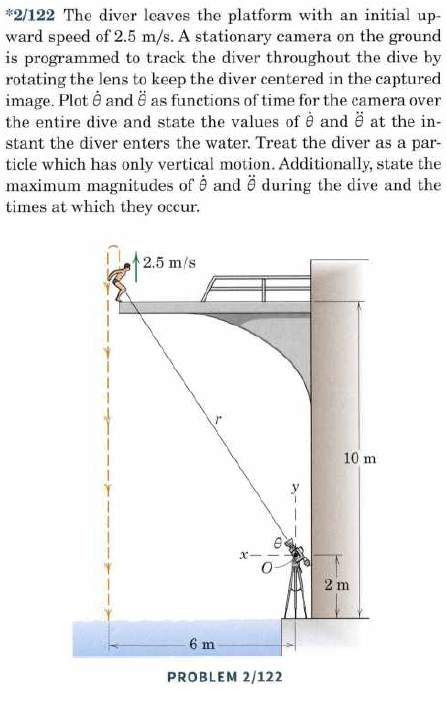

syms t v_theta theta_dot
v(t) = 2.5 - (9.81 * t)

$$v(t) = \frac{5}{2}-\frac{981\,t}{100}$$

x(t) = int(v(t), t) + 8

$$x(t) = 8-\frac{t\,\left(981\,t-500\right)}{200}$$

t_vand = vpa(solve(-2 == x(t), t))

$$t\_vand = \left(\begin{array}{c} -1.195564988927244123685719384611\\ 1.7052489848497721563054951236528 \end{array}\right)$$

t_vand = t_vand(2)

$$t\_vand = 1.7052489848497721563054951236528$$

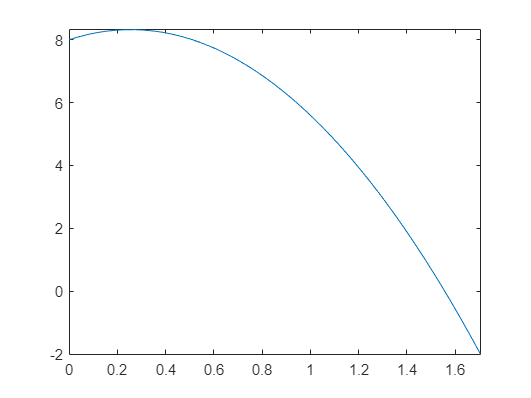

fplot(x(t))
xlim([0, double(t_vand)])


r(t) = sqrt(6^2+x(t)^2)

$$r(t) = \sqrt{{\left(\frac{t\,\left(981\,t-500\right)}{200}-8\right)}^{2}+36}$$


v_r(t) = diff(r(t), t)

$$v\_r(t) = \frac{\left(\frac{981\,t}{100}-\frac{5}{2}\right)\,\left(\frac{t\,\left(981\,t-500\right)}{200}-8\right)}{\sqrt{{\left(\frac{t\,\left(981\,t-500\right)}{200}-8\right)}^{2}+36}}$$



%v_theta(t) = v(t) * cos(theta(t))

v_theta = solve(sqrt(v_r^2 + v_theta^2) == v, v_theta)

$$v\_theta = \left(\begin{array}{c} -12\,\sqrt{\frac{1}{962361\,t^{4}-981000\,t^{3}-2889200\,t^{2}+1600000\,t+4000000}}\,\left(981\,t-250\right)\\ 12\,\sqrt{\frac{1}{962361\,t^{4}-981000\,t^{3}-2889200\,t^{2}+1600000\,t+4000000}}\,\left(981\,t-250\right) \end{array}\right)$$

v_theta(t) = v_theta(1)

$$v\_theta(t) = -12\,\sqrt{\frac{1}{962361\,t^{4}-981000\,t^{3}-2889200\,t^{2}+1600000\,t+4000000}}\,\left(981\,t-250\right)$$


v_theta(t)

$$ans = -12\,\sqrt{\frac{1}{962361\,t^{4}-981000\,t^{3}-2889200\,t^{2}+1600000\,t+4000000}}\,\left(981\,t-250\right)$$


theta_dot(t) = solve(v_theta == r * theta_dot, theta_dot)

$$theta\_dot(t) = -\frac{12\,\sqrt{\frac{1}{962361\,t^{4}-981000\,t^{3}-2889200\,t^{2}+1600000\,t+4000000}}\,\left(981\,t-250\right)}{\sqrt{{\left(\frac{t\,\left(981\,t-500\right)}{200}-8\right)}^{2}+36}}$$

theta_ddot(t) = diff(theta_dot(t), t)

$$theta\_ddot(t) = \begin{array}{l} \frac{12\,\sqrt{\frac{1}{\sigma_{1}}}\,\left(\frac{981\,t}{100}-\frac{5}{2}\right)\,\left(981\,t-250\right)\,\sigma_{3}}{{\left({\sigma_{3}}^{2}+36\right)}^{3/2}}-\frac{11772\,\sqrt{\frac{1}{\sigma_{1}}}}{\sigma_{2}}-\frac{6\,\left(981\,t-250\right)\,\left(-3849444\,t^{3}+2943000\,t^{2}+5778400\,t-1600000\right)}{\sigma_{2}\,\sqrt{\frac{1}{\sigma_{1}}}\,{\sigma_{1}}^{2}}\\ \mathrm{where}\\ \sigma_{1}=962361\,t^{4}-981000\,t^{3}-2889200\,t^{2}+1600000\,t+4000000\\ \sigma_{2}=\sqrt{{\sigma_{3}}^{2}+36}\\ \sigma_{3}=\frac{t\,\left(981\,t-500\right)}{200}-8 \end{array}$$



vpa(theta_dot(t_vand))

$$ans = -2.1342738812064397280035360744552$$

vpa(theta_ddot(t_vand))

$$ans = 1.56525$$

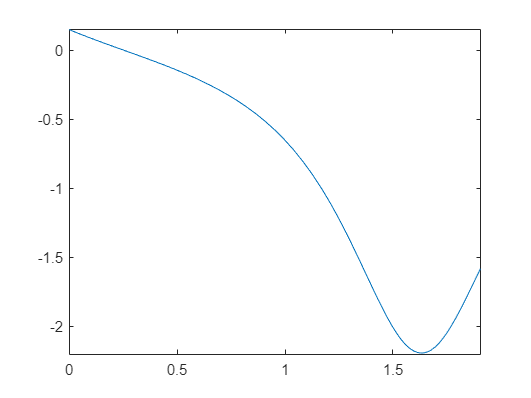


figure
fplot(theta_dot(t))
xlim([0, double(t_vand+0.2)])



t_lin = vpa(linspace(0,t_vand,100))

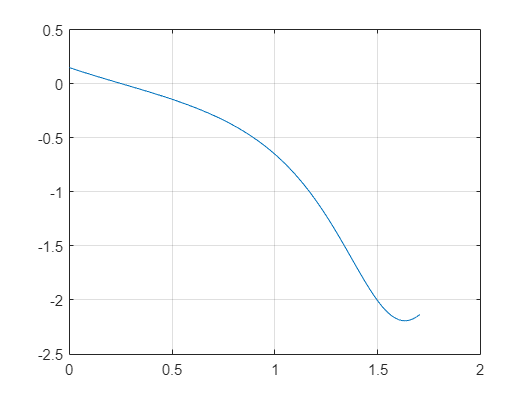

figure(2)
plot(t_lin, theta_dot(t_lin))
grid("on")



theta(t) = atan(x(t)/6)

$$theta(t) = -\mathrm{atan}\left(\frac{t\,\left(981\,t-500\right)}{1200}-\frac{4}{3}\right)$$

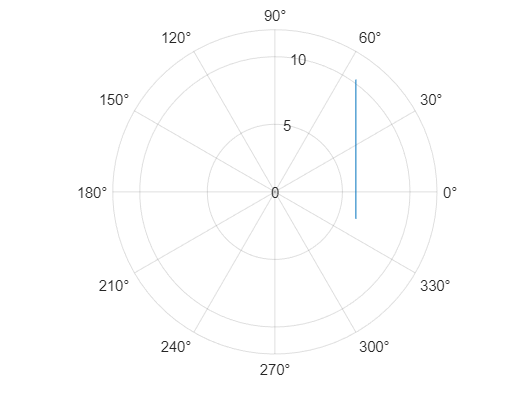



polarplot(double(theta(t_lin)),r(t_lin))


theta_0 = atand(8/6)

theta_0 = 53.1301